# Cine to Sparse converter

## Scheme

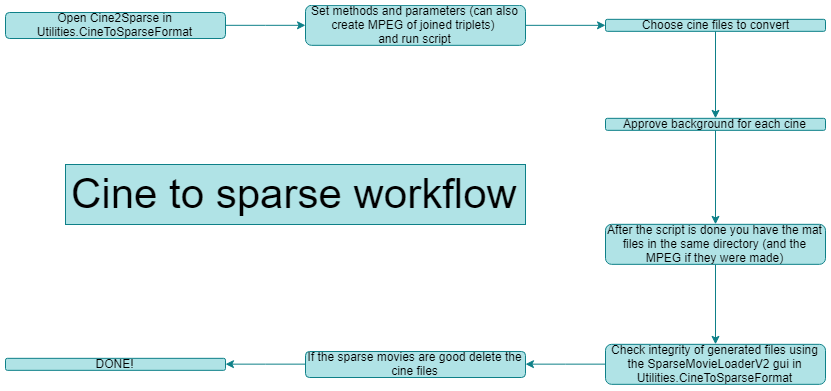

## Description

Converts cine files to mat files with frames containing moving objects in a sparse format, and a metadata struct

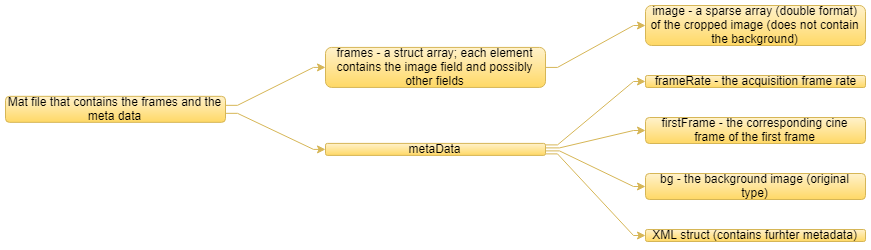

## Code

### Initialization

set methods and parameters:

bgMethod='Single movie max';
bgNSample=100;
filterMethod='Area filter';
createMpgTriplets=1; % requires files of the form mov#_cam#
mpgFrameRate=30;
mpgQuality=25;

UI to get a list of filenames and initialize variables:

[fileNames,folderPath] = uigetfile('*.cine','Select Cine\s to convert',...
    'MultiSelect', 'on');
if isequal(fileNames,0)
   disp('User selected Cancel; end of session')
   return
end
if ~iscell(fileNames)
    fileNames={fileNames};
end
fileInd=0;

Load PhantomSDK if needed: (!!take care: PHANTOM SDK LOADING NEEDS TO BE REVISED GLOBALLY!!)

if ~exist('getCinMetaData','file')
    run('..\PhantomSDK\runMeFirst.m')
end

Add utilities to path (needs to be run in this script's directory)

addpath('..');

Create MPEG movie of triplets:

if createMpgTriplets
    if mod(length(fileNames),3)~=0
        error('only multiples of three!')
    else
        for tripletInd=1:(length(fileNames)/3)
            VideoEditing.Join3Cines(cellfun(@(x) fullfile(folderPath,x),fileNames((1:3)+3*(tripletInd-1)),'UniformOutput',false),...
                mpgFrameRate,mpgQuality)
        end
    end
end

### Loop on cine files in the path

while fileInd<length(fileNames)
    fileInd=fileInd+1;

Load the cine file:

    cinePath=fullfile(folderPath,fileNames{fileInd});
    cineMetaData = getCinMetaData(cinePath) ;
    cineData  = myOpenCinFile(cinePath);
    disp(cinePath);

Choose the background generation algorithm:

    switch strtok(bgMethod)
        case 'Manual input'
            [file,path] = uigetfile('*.*',['Choose background image for ',fileNames{fileInd}]);
            if isequal(file,0)
               disp('User selected Cancel; skipping cine');
               continue
            else
               metaData.bg = imread(fullfile(path,file));
            end
        case 'Single'
            metaData.bg = CineToSparseFormat.FindCineBG(cinePath,bgNSample,bgMethod);
    end

Generate the background image and check with user if its good:

    checkFig=figure;
    set(gcf,'Visible','on')
    imshow(metaData.bg,[])
    answer = questdlg('Is background good?', ...
        'Background Check', ...
        'Yes','No','Yes');
    delete(checkFig)
    switch answer
        case 'Yes'
        otherwise
            disp('Background is bad; skipping cine');
            continue
    end

Assign and initialize variables

    numOfImages = cineMetaData.lastImage-cineMetaData.firstImage+1 ;
    clear frames
    frames(numOfImages,1)=struct;%#ok<SAGROW>
    metaData.startFrame=cineMetaData.firstImage;
    metaData.frameRate=cineMetaData.frameRate;
    metaData.frameSize=size(metaData.bg);
    saveInd=0;

#### Loop on frames in the cine

    for imageInd = 1:numOfImages
        saveInd=saveInd+1;
        if ~mod(imageInd,50)
            disp([num2str(imageInd),'/',num2str(numOfImages)]);
        end
        inpIm = myReadCinImage(cineData, cineMetaData.firstImage+imageInd-1);
        mask=imbinarize(metaData.bg-inpIm,0.05);
        switch filterMethod
            case 'Largest blob'
                mask=bwareafilt(mask,1); % choose only the largest blob
            case 'Area filter'
                mask=bwareaopen(mask,50); % made for multiple insects in frame
        end

fix zeros inside mask to store them in the sparse matrix (black but nonzero!)

        inpIm(mask&(inpIm==0))=1;

copy only what differs from background and save as sparse matrix

        [row,col,v] = find(cast(mask, class(inpIm)).*inpIm);
        frames(saveInd).indIm=uint16([row,col,v]);
    end

Save xml file and add to metaData

    PhLVRegisterClientEx([], PhConConst.PHCONHEADERVERSION);
    PhSetUseCase(cineData.cineHandle, PhFileConst.UC_SAVE);
    % set to save xml
    pXML = libpointer('bool',true);
    PhSetCineInfo(cineData.cineHandle,PhFileConst.GCI_SAVEXML,pXML);
    % Prepare a save name and path for the cine
    tempFileName='C:\just4xml\just4xml';
    pInfVal = libpointer('cstring', [tempFileName,'.cine']);
    PhSetCineInfo(cineData.cineHandle, PhFileConst.GCI_SAVEFILENAME, pInfVal);
    
    imgRng = get(libstruct('tagIMRANGE'));
    imgRng.First = cineMetaData.firstImage;
    imgRng.Cnt = 1;
    pimgRng = libpointer('tagIMRANGE', imgRng);
    PhSetCineInfo(cineData.cineHandle, PhFileConst.GCI_SAVERANGE, pimgRng);
    PhWriteCineFile(cineData.cineHandle);
    metaData.xmlStruct=CineToSparseFormat.betterXml2struct([tempFileName,'.xml']).chd;
    delete([tempFileName,'.cine'])
    delete([tempFileName,'.xml'])

Check that file isn't too large (problems with object segmentation)

    framesWhos=whos('frames');
    if framesWhos.bytes>10^9
        warndlg('File is Extremely large, something is probably wrong!')
    end

save the frame and metadata variables:

(v7.3 is important for partial loading of images)

    save(fullfile(folderPath,...
        [fileNames{fileInd}(1:(strfind(fileNames{fileInd},'.cine')-1)),'_sparse']),...
        'frames','metaData','-v7.3')
    myCloseCinFile(cineData);
end